# Sensitivity Analysis 

This workflow analyzes how sensitive various parameters are when you performthe techno economic analysis of microgrids. 

## Sensitive Variables

In this workflow, you can choose any of the sensitive variables and observe the impact of that particular variable in the overall design of the microgrid.

MicrogridTechnoEconomic;
sensitivityAnalysis.enable = true;
sensitivityAnalysis.var = "Grid Price";
sensitivityAnalysis.val = 0.1:0.2:0.5;
sensitivityAnalysis.components = {'batteryEnergyRating','solarRating','windRating','generatorRating'};sensitivityAnalysis.components = {'batteryEnergyRating','solarRating','windRating','generatorRating'};

### Multiple Optimizations

Once you choose the sensitive variable, this example performs multiple optimizations are done to observe the effect of that variable on the overall design.

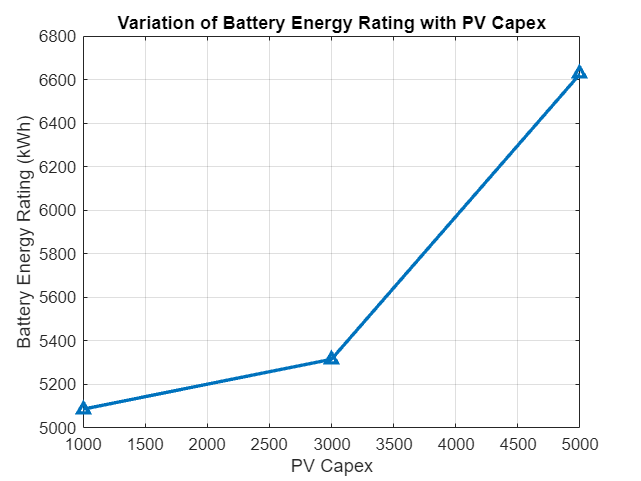

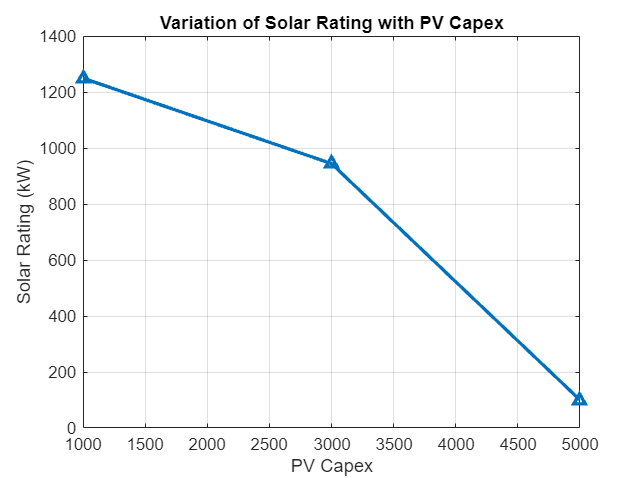

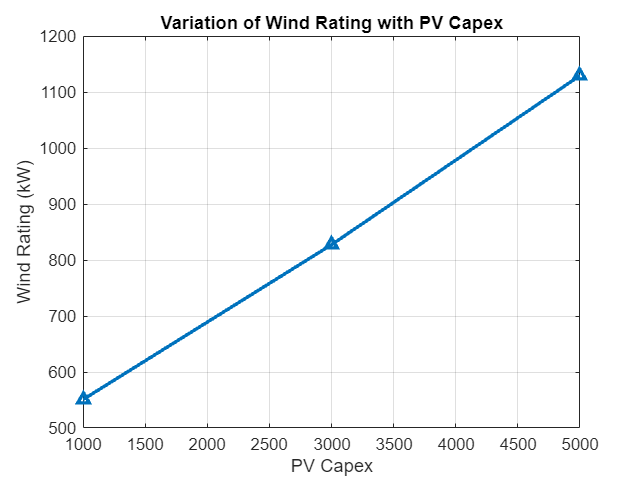

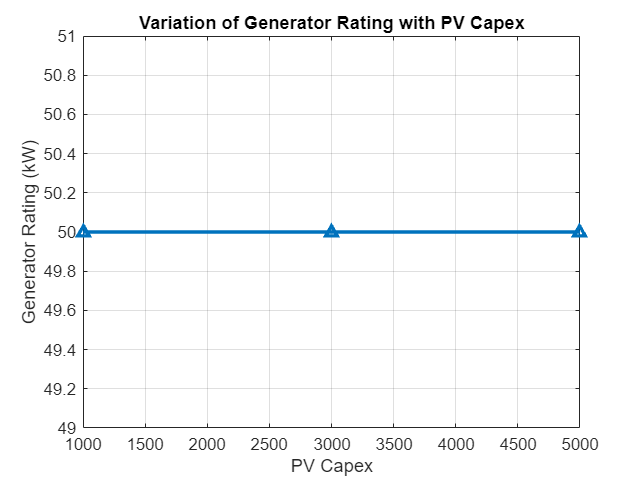

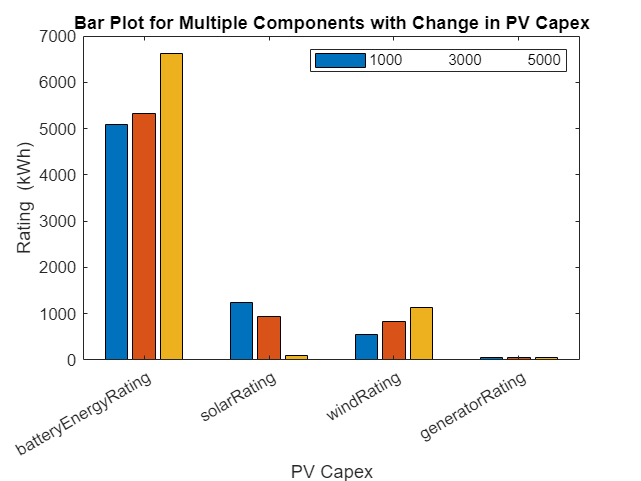

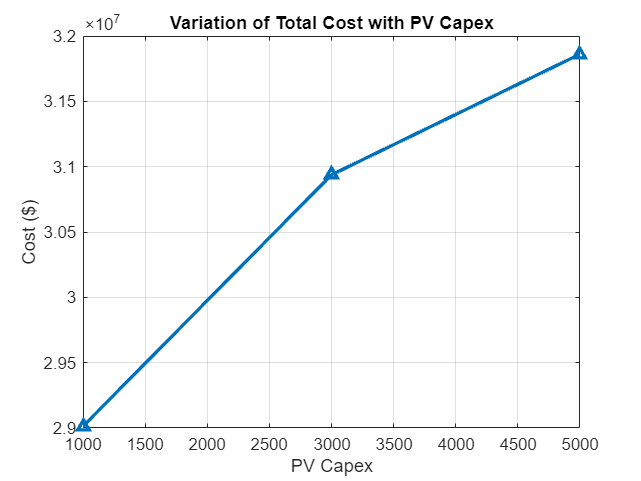

varLength = length(sensitivityAnalysis.val);
batteryVal = ones(varLength,1);
solarVal = ones(varLength,1);
windVal = ones(varLength,1);
generatorVal = ones(varLength,1);
costVal = ones(varLength,1);

parfor optIdx = 1:varLength
    [batteryVal(optIdx),solarVal(optIdx),windVal(optIdx),generatorVal(optIdx),costVal(optIdx)] = runSensitivity(sensitivityAnalysis.var,sensitivityAnalysis.val(optIdx)); %#ok<*PFBNS>
end
sensitivityAnalysis.result.batteryEnergyRating= batteryVal;
sensitivityAnalysis.result.solarRating = solarVal;
sensitivityAnalysis.result.windRating = windVal;
sensitivityAnalysis.result.generatorRating = generatorVal;
sensitivityAnalysis.result.cost = costVal;

plotSensitivityAnalysis(sensitivityAnalysis);

Copyright 2024 The MathWorks, Inc.